%import the error data that will allow for a good starting point for the membership funcitons
concentric = readmatrix('C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Front Concentric Error.txt');
eccentric = readmatrix('C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Front Eccentric Error.txt');

% Compute means and standard deviations
con_mean = mean(concentric, 2);
con_std = std(concentric, 0, 2);
ecc_mean = mean(eccentric, 2);
ecc_std = std(eccentric, 0, 2);

%Extract only the mean and standard deviation of the 2nd feature (knee
%separation). Then average the concentric and eccentric.
mu = mean([con_mean(3), ecc_mean(3)])

mu = -8.4998e-17

sigma = mean([con_std(3), ecc_std(3)])

sigma = 0.2265

x1 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Wide Feet Data.txt");
y1 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Wide Feet Labels.txt");
x2 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Very Close Data.txt");
y2 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Very Close Labels.txt");
x3 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very ModeratelyVery Feet Data.txt");
y3 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very ModeratelyVery Feet Labels.txt");
x4 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Moderately Feet Data.txt");
y4 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Moderately Feet Labels.txt");
x5 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Moderately Close Data.txt");
y5 = readmatrix("C:\\Users\\Cian\\1 FYP Code\\Code_with_git\\Prototype 3\\Feedback\\Data\\Training Data - Fuzzy Logic\\Feet\\Very Moderately Close Labels.txt");

x1

x1 =     1.2334    1.2298    1.2477
    1.2279    1.2219    1.2395
    1.2100    1.2143    1.2387
    1.3349    1.3146    1.2094
    1.2719    1.2582    1.2258
    1.2088    1.2519    1.2244



%concatenate the data and labels
X = cat(1, x1, x2, x3, x4, x5);
Y = cat(1, y1, y2, y3, y4, y5);

%reshape X and Y to be one dimensional
X1d = X(:);
Y1d = Y(:);

%Shuffle
perm = randperm(numel(X1d));
Xtrain = X1d(perm)

Xtrain =     0.9204
    0.5897
    1.2298
   -0.7345
   -0.3613
    0.5808
    0.5535
    1.2719
    0.9442
   -0.6369


Ytrain = Y1d(perm)

Ytrain =     0.7500
    0.5000
    1.0000
   -1.0000
   -0.5000
    0.7500
    0.5000
    1.0000
    0.7500
   -1.0000



% Define tuning options
options = tunefisOptions(...
    "Method", "patternsearch", ...
    "OptimizationType", "tuning");

% Configure patternsearch parameters
options.MethodOptions = optimoptions('patternsearch', ...
    'MaxIterations', 30, ...
    'InitialMeshSize', 0.01, ...
    'MeshTolerance', 1e-3, ...
    'PollMethod', 'GPSPositiveBasis2N');

%create a cell array to store fis instances
fis1_instances = cell(1, 3);

%loop to create each optimised fis
for i = 1:3
    %create an instance of FIS1
    fis = FIS1Foot(sigma, mu, sprintf('fis1%d',i));

    %obtain only the input membership functions for tuning
    [in, ~, ~] = getTunableSettings(fis);

    %Exclude tuning of the "correct" MF (this was already chosen with data).
    % in(1).MembershipFunctions(1).Parameters.Free = [0 0];

    % Choose the optimisation parameters
    options.MethodOptions.MaxIterations = 50;        % Limited iterations
    options.MethodOptions.InitialMeshSize = 0.01;     % Small step size
    options.MethodOptions.MeshTolerance = 1e-4;      % Moderate precision
    % options.MethodOptions.PollMethod = 'GPSPositiveBasis2N'; % Reliable polling

    %tune the system
    fis1_tuned = tunefis(fis, in, Xtrain, Ytrain, options);

    %add the system to the instance array
    fis1_instances{i} = fis1_tuned;
end

patternsearch stopped because it exceeded options.MaxIterations.
patternsearch stopped because it exceeded options.MaxIterations.
patternsearch stopped because it exceeded options.MaxIterations.



fis11 = fis1_instances{1};
fis12 = fis1_instances{2};
fis13 = fis1_instances{3};

fis11.Inputs(1).MembershipFunctions

ans =   1×3 fismf array with properties:

    Type
    Parameters
    Name

  Details:
            Name          Type           Parameters    
         ___________    _________    __________________

    1    "Correct"      "gaussmf"    0.22654       0.54
    2    "Large_neg"    "sigmf"        -11.8         -1
    3    "Large_pos"    "sigmf"           15       0.42


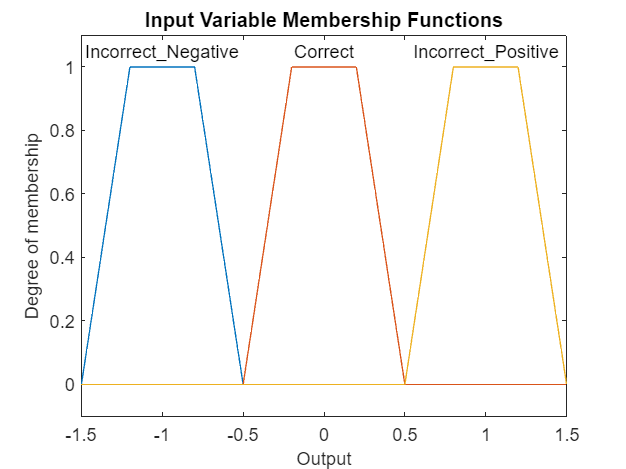

figure;
plotmf(fis11, 'output', 1);  % Change 1 to the index of the input you want to plot
title('Input Variable Membership Functions');

% fuzzyLogicDesigner(fis11);

temp = FIS1Foot(sigma, mu, 'testfis')

temp =   mamfis with properties:

                       Name: "testfis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
    DisableStructuralChecks: 0
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×3 fisrule]

	See 'getTunableSettings' method for parameter optimization.


val = 0.75;
evalfis(temp,val)

ans = 0.8380

evalfis(fis11,val)

ans = 0.5708

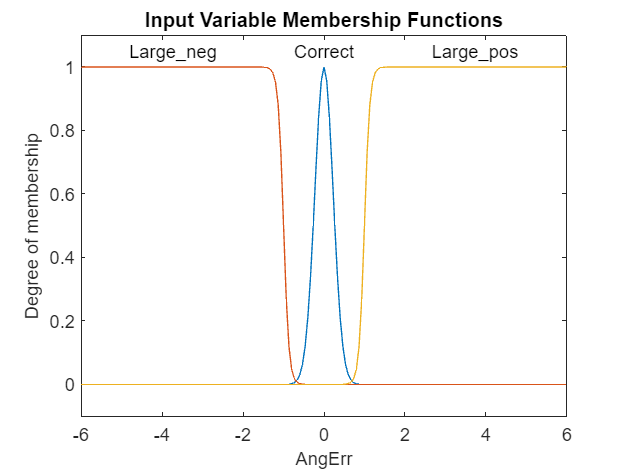


figure;
plotmf(temp, 'input', 1);  % Change 1 to the index of the input you want to plot
title('Input Variable Membership Functions');

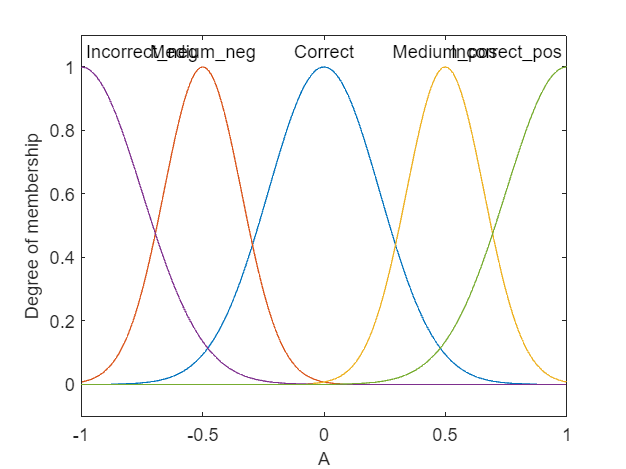

%create the next layer
fis21 = FIS2('fis21');
fis22 = FIS2('fis22');

figure;
plotmf(fis21, 'input', 1);

% Change 1 to the index of the input you want to plot
% title('Input Variable Membership Functions');

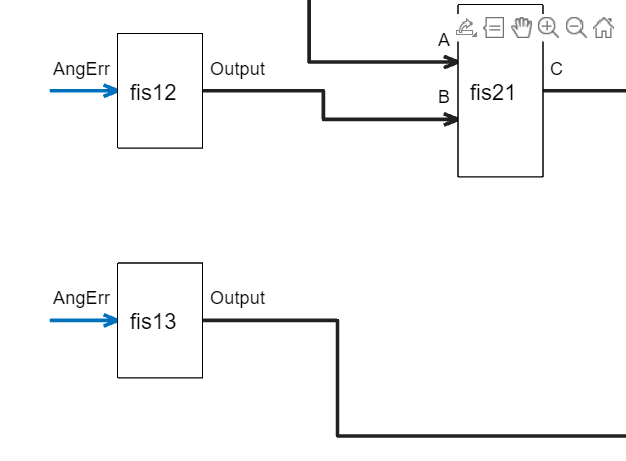

%create connections
con1 = ["fis11/Output" "fis21/A"];
con2 = ["fis12/Output" "fis21/B"];
con3 = ["fis21/C" "fis22/A"];
con4 = ["fis13/Output" "fis22/B"];

%create tree
fisT = fistree([fis11 fis12 fis13 fis21 fis22],[con1;con2;con3;con4]);
plot(fisT)

% Get tunable parameters (inputs, outputs, rules)
[in, out, rule] = getTunableSettings(fisT);

% Just tune the MF's of FIS21 and FIS22
for i = 1:numel(in)
    % Get the FIS name associated with the input MF
    fisName = in(i).FISName; % Access the FIS name
    
    % Freeze MF's for all FIS except fis21 and fis22
    if ~(strcmp(fisName, "fis22") || strcmp(fisName, "fis21"))
        % Loop through each membership function in the input
        for j = 1:numel(in(i).MembershipFunctions)
            in(i).MembershipFunctions(j).Parameters.Free = [0, 0]; % Freeze MF parameters
        end
    else
        %for fis21 and fis22 only allow the standard deviation to change
        for j = 1:numel(in(i).MembershipFunctions)
            in(i).MembershipFunctions(j).Parameters.Free = [1, 0];
        end
    end
end

% Reshape the data and labels
x_new = cat(1,x1,x2,x3,x4,x5);
y_resh = cat(1,y1, y2,y3,y4,y5);

% Find the index of the element with the largest magnitude in each row of y_resh
[~, ind] = max(abs(y_resh), [], 2);

% Extract the actual elements (not their absolute values) corresponding to these indices
y_new = y_resh(sub2ind(size(y_resh), (1:size(y_resh, 1))', ind));
y_new

%shuffle
perm_new = randperm(size(x_new, 1));
Xtrain_new = x_new(perm_new, :)
Ytrain_new = y_new(perm_new)

%now set up the tuning options.
options = tunefisOptions(...
    "Method", "patternsearch", ...
    "OptimizationType", "tuning");

% Configure patternsearch parameters
options.MethodOptions = optimoptions('patternsearch', ...
    'MaxIterations', 30, ...
    'InitialMeshSize', 0.5, ...
    'MeshTolerance', 1e-4, ...
    'PollMethod', 'GPSPositiveBasis2N');

%tune the rules
fisTree = tunefis(fisT, in, x_new, y_new, options)

u = getFISCodeGenerationData(fis11)
u1 = getFISCodeGenerationData(fis21)
u2 = getFISCodeGenerationData(fis22)
save("C:\Users\Cian\OneDrive\Documents\Imperial\Year 4\FYP\Trained MATLAB FIS\feet_f.mat", "u", "u1", "u2")

fis11.Inputs(1).MembershipFunctions

evalfis(fis11,0)
evalFis([0.514167794, 0.512111, 0.51725777], fisT)
% fuzzyLogicDesigner(fis22);

function res = evalFis(data, FIS)
    result = evalfis(FIS, data);

    if result < -0.6
        res = sprintf('Incorrect: Feet too close (Score: %.2f)', result);
    elseif result >= -0.6 && result < -0.2
        res = sprintf('Partially Incorrect: Feet too close (Score: %.2f)', result);
    elseif result >= -0.2 && result < 0.2
        res = sprintf('Correct, well done! (Score: %.2f)', result);
    elseif result >= 0.2 && result < 0.6
        res = sprintf('Partially Incorrect: Feet too far apart (Score: %.2f)', result);
    else
        res = sprintf('Incorrect: Feet too far apart (Score: %.2f)', result);
    end
end